## Introduction

Hello and welcome to the IRACEMA User Guide.

IRACEMA is a group of MATLAB scripts made to work with Isogeometric Analysis. It was created by Guilherme Henrique da Silva and maintained by Guilherme Henrique da Silva and André Demétrio Magalhães for da Silva's Doctorate Thesis. The objective of IRACEMA is to provide an intuitive and didatic approach to learning Isogeometric Analysis.

We will provide through these Live Scripts examples and guides to how IRACEMA works. These will follow the pattern of Syntax, Description and Examples, much like Mathwork's MATLAB online help.

IRACEMA is divided in three parts: **NURBS, IGA **and **Examples**.

**NURBS **is where every algorithm of the Geometry class is included. We have most of Piegl and Tiller's The NURBS Book's Algorithms programmed in this class.

**IGA** is where the Assemblies, Shape Functions and Boundary Condition enforcement algorithms are. These are a compilation of Hughe's Isogeometric Analysis book and several papers. Here also lies da Silva's Doctorate work, mostly on Schwarz Algorithm examples.

**Examples** is self-explanatory. We hope to have working Examples of most used Differential Equations here, one day.

## Geometry Class Constructors

The Geometry Class is the heart of IRACEMA. It is used for geometry construction, basis function evaluation, derivative evaluation, etc. The Geometry class constructor can be called in three different ways:

Naturally, these are the constructor for parametric curves of one, two and three parametric dimensions. Let's play a bit with the inputs and create a line:

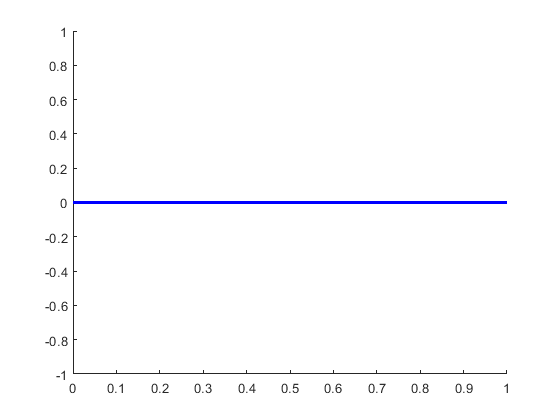

p = 1; % Polynomial Degree of the Parametric Direction
KnotVector = [0 0 1 1]; % KnotVector for a p = 1 NURBS Curve
ControlPoints = {[0 0 0 1], [1 0 0 1]};
Model = Geometry('curve',p,KnotVector,ControlPoints);
figure(1)
Model.plot_geo; % Plot the geometry

As you can see, we have constructed a Line using the Geometry Class.

Don't worry. You won't  have to manually create your models. The same can be achieved using our geometry construction algorithms, such as:

point1 = [0 0 0];
point2 = [1 0 0];
Line1 = geo_line(point1, point2); % Create a Geometry Class Object in the form of a line crossing two points.
figure(2)
Line1.plot_geo;

Which is the same line as before. We will not construct a ruled surface between two lines, using the geo_ruled function.

First, lets make another line and call it Line2:

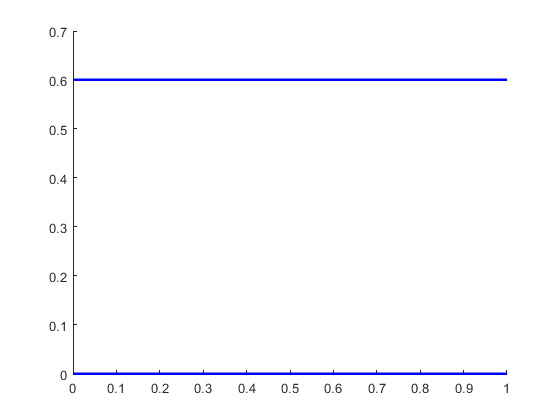

point3 = [0 0.6 0];
point4 = [1 0.6 0];
Line2 = geo_line(point3, point4);
figure(3)
Line1.plot_geo; % Our first line
hold on
Line2.plot_geo; % The line we just made

Now, to make a ruled surface:

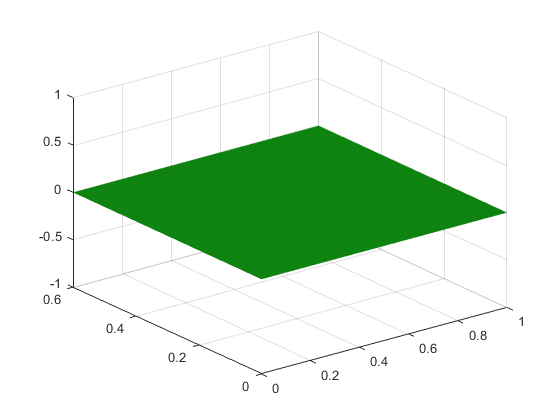

Surface = geo_ruled(Line1,Line2);
figure(4)
Surface.plot_geo;

Lets extrude this plane to make a solid, 3D plate by using geo_extrude:

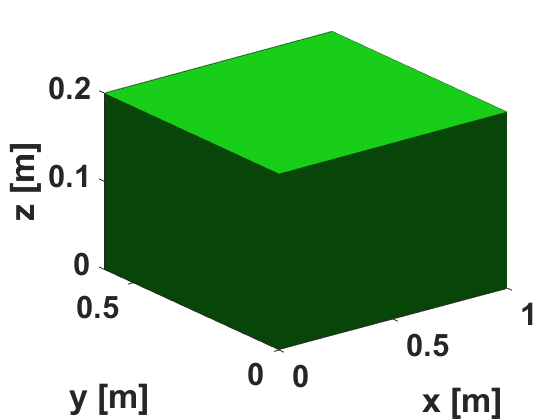

vector = [0 0 0.2]; % Direction and magnitude of extrusion
Plate = geo_extrusion(Surface,vector);
figure(5)
Plate.plot_geo;

There are several other constructor of geometries in the Geometry Class. Check out their documentation later:

## Geometry Class Atributes and Methods

By acessing a Geometry Class object, we can see it's atributes:

Plate

Plate =   Geometry with properties:

        type: 'volume'
          nu: 1
          pu: 1
           U: [0 0 1 1]
          nv: 1
          pv: 1
           V: [0 0 1 1]
          nw: 1
          pw: 1
           W: [0 0 1 1]
          PX: [2×2×2 double]
          PY: [2×2×2 double]
          PZ: [2×2×2 double]
      weight: [2×2×2 double]
          Pw: [2×2×2 CPOINT]
    PlotProp: [1×1 struct]


Currently, our Geometry Object is composed of a trilinear basis, each one with one knot-length. This can be changed by two methods of the Geometry Class: KnotRefine and DegreeElevate.

Let's start first by plotting the basis function of the first parametric direction*

*The first, second and third parametric directions are conventionally named *u, v* and *w. *Their KnotVectors are named *U, V* and *W*.

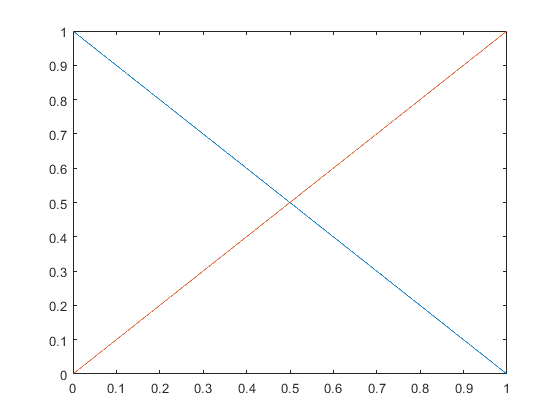

figure(6)
Plate.plot_basis(1); % 1 because we want to plot the basis of the first parametric direction. 2 for v, 3 for w.

Let's first elevate the degree of the polynomial basis of the first direction to p = 4 by using the DegreeElevate method, given by the syntax:

Plate.DegreeElevate(3,1); % We wish to elevate 3 degrees in the first parametric direction.
Plate

Plate =   Geometry with properties:

        type: 'volume'
          nu: 4
          pu: 4
           U: [0 0 0 0 0 1 1 1 1 1]
          nv: 1
          pv: 1
           V: [0 0 1 1]
          nw: 1
          pw: 1
           W: [0 0 1 1]
          PX: [5×2×2 double]
          PY: [5×2×2 double]
          PZ: [5×2×2 double]
      weight: [5×2×2 double]
          Pw: [5×2×2 CPOINT]
    PlotProp: [1×1 struct]


As we can see, the polynomial degree of the first parametric direction has been elevated. What hapenned to the basis functions?

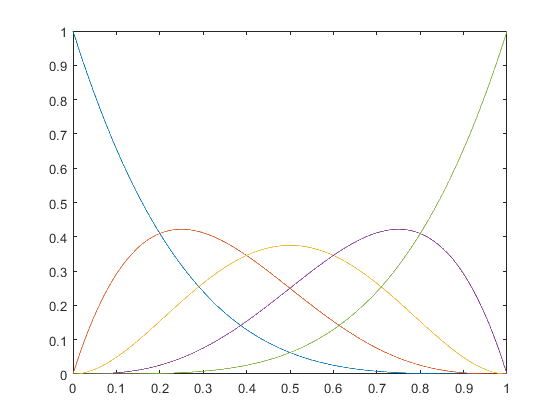

figure(7)
Plate.plot_basis(1);

Now we want to add knots in the first parametric direction. This is done through the KnotRefine method. The syntax is:

Let's add 10 knots to the Geometry. These knots have to obey one rule: they must be located in the **open** interval between 0 and 1.

KnotsToAdd = linspace(0,1,12); % The knots I want to add will be equally spaced between 0 and 1.
KnotsToAdd = setdiff(KnotsToAdd,[0, 1]); % Here, we make the interval be 10 equally spaced knots between 0 and 1, because the interval must be open
Plate.KnotRefine(KnotsToAdd,1);
Plate.U % Printing the KnotVector of the First Parametric Direction

ans =          0         0         0         0         0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0000    1.0000    1.0000    1.0000


Now, let's see what hapenned to the basis functions:

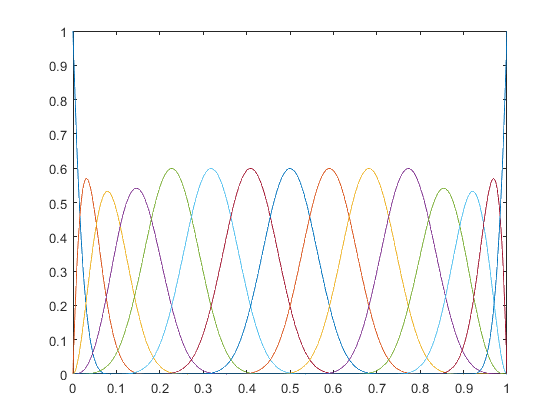

figure(8)
Plate.plot_basis(1)

And this concludes the Introduction to the Geometry Class.